N = 5; %Количество элементов в массиве (нечётно)
d = 0.1; %Расстояние между элементами массива
%nu =1e3; %Частота

freq_plot_flag = false; %true; Рисовать ли двумерную зависимость от частоты или нет

w = 1/N; %Комплексный весовой коэффициент каждого элемента
phi_limits = [1,180]; %Границы ДН по азимутальному углу в градусах [от,до]
nu_limits = [500,1000]; %Границы частоты для семейства кривых ДН [от,до]
phi_step = 1; %Шаг изменения угла ДН по азимутальному углу
D = zeros((nu_limits(2)-nu_limits(1)+1),(phi_limits(2)-phi_limits(1)+1)); %Инициализируем массив, который будет содержать ДН


c = 335; %Скорость звука

    for nu = nu_limits(1):20:nu_limits(2)
        for phi = phi_limits(1):phi_step:phi_limits(2)
            for n = fix(-(N-1)/2):1:fix((N-1)/2) %Проходимся по всем микрофонам
                D((nu-nu_limits(1)+1),(phi-phi_limits(1)+1)) = D((nu-nu_limits(1)+1),(phi-phi_limits(1)+1)) + w*exp(1j*2*pi*n*d*cos(phi*pi/180)/(c/nu));
            end
        end
    end

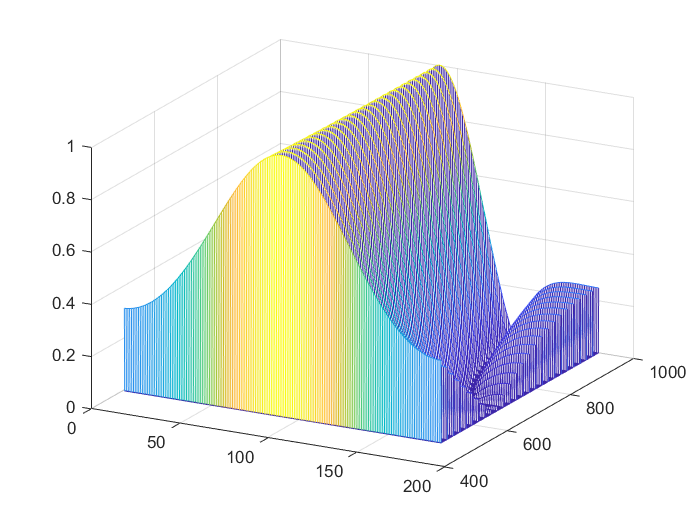

mesh((phi_limits(1):1:phi_limits(2)),(nu_limits(1):1:nu_limits(2)),abs(D));
colormap default;

view([28.199 25.192])